%Universidad del Cauca - 2021-1
%Teoria de las telecomunicaciones 1
%Trabajo 2 - Grupo 12 - Nicolas Chicaiza y Nicolas Zambrano

clear; %Limpio Espacio de trabajo
clc;

A=1; %Amplitud rampa (Igual al taller 1)
sh=0.5; %Desplazamiento en el tiempo (Igual al taller 1)
T=1; %Periodo rampa (Igual al taller 1)


%fr=1/T; %Frecuencia
%fs=(1/T):1/T:(1/T); %Normalizacion vector de Frecuencia

np=0.01; %Espacio numerico definido en el periodo de la funcion (np=Numero de muestras en un periodo)
t=-(T):T*np:(T); %Limites del espacio numerico (eje de abscisas ¨tiempo¨)


ramp=(A/T)*(t); %Defino la pendiente de las rampas y creo el vector rampa con respecto al tiempo
ps=ramp.*rectpuls((t)-(T/2),T); %Acoto el vector rampa con un pulso rectangular de origen en 0 y ancho Tr
%dds=zeros(size(t)); %Incializo variable
% shft=0; % Incializo variable
% for k=-2:1:1 %en este ciclo roto el vector rampa ps y voy generando la funcion diente de sierra repetida por 4 periodos
% shft=T*k*(1/np);
% dds=dds+circshift(ps,fix(shft)); %sumatoria de generacion
% end

%---------------------------CALCULO SIMBOLICO TRANSFORMADA--------------------------
%---------------------------Transformada pulso rampa--------------------------
syms x f;
dif=((A/T)*(x+sh)*exp(-i*2*pi*f*x)); %Expresion dentro de la integral de la transformada de Fourier
trfu=int(dif,[0-sh T-sh]) %Integral definida en el periodo de la rampa

$$trfu = \frac{\cos\left(\pi \,f\right)\,\mathrm{i}}{2\,f\,\pi }+\frac{\sin\left(\pi \,f\right)}{2\,f\,\pi }-\frac{\sin\left(\pi \,f\right)\,\mathrm{i}}{2\,f^{2}\,\pi^{2}}$$

trfu=simplify(abs(trfu))

$$trfu = \frac{\left|\sin\left(\pi \,f\right)-\pi \,f\,\cos\left(\pi \,f\right)+\pi \,f\,\sin\left(\pi \,f\right)\,\mathrm{i}\right|}{2\,\pi^{2}\,{\left|f\right|}^{2}}$$

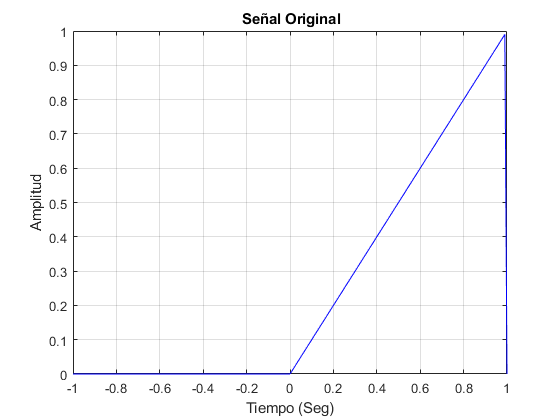

%ciclo for
%etf=subs(trfu)
%ciclo for
%-----------------------------------------------------------------------------

%--------------------CALCULO FFT---------------------------
rafu=fft(ps);
rafu=abs(rafu);
%normalizar frecuencia
f=1./t;%prueba de dominio en frecuencia
%-----------------------------------------------------------------------------


%--------------------Graficacion de Resultados---------------------------
plot(t,ps,'b'),grid on,xlabel 'Tiempo (Seg)', ylabel Amplitud;xlim([-T T]); %Graficacion de Resultados
title('\bf Señal Original');

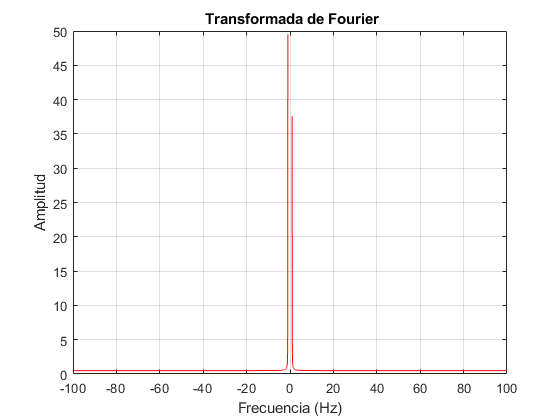

plot(f,rafu,'r'),grid on,xlabel 'Frecuencia (Hz)', ylabel Amplitud;%xlim([-T T]); %Graficacion de Resultados
title('\bf Transformada de Fourier');

% stem(fs,mag),grid on,xlabel 'Frecuencia (Hz)', ylabel Amplitud; %Graficacion de Resultados
% title('\bf Espectro de Amplitud');
%-----------------------------------------------------------------------------